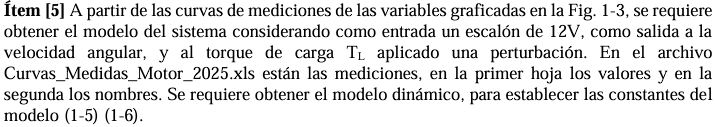

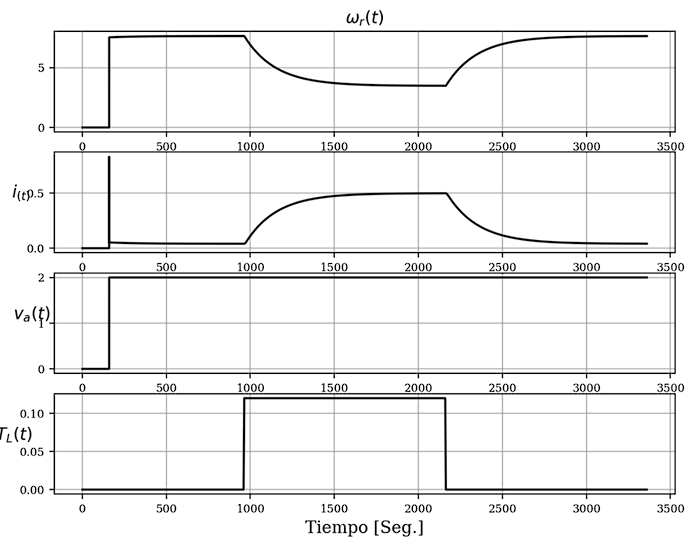

Lectura de datos :  

clear all; clc; close all;

opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Hoja1";
opts.DataRange = "A2:E1500";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("C:\Users\Maca\Documents\UNC\4toAÑO\1CUATRI\SC2\Folder Github TP´s\Control-System-II-TP-s\TP1\documentation\Curvas_Medidas_Motor_2025_v.xls", opts, "UseExcel", false);

t = tbl.VarName1;
Wr = tbl.VarName2;
Ia= tbl.VarName3;
Va= tbl.VarName4;
Tq = tbl.VarName5;
clear opts tbl

Gráficas: 

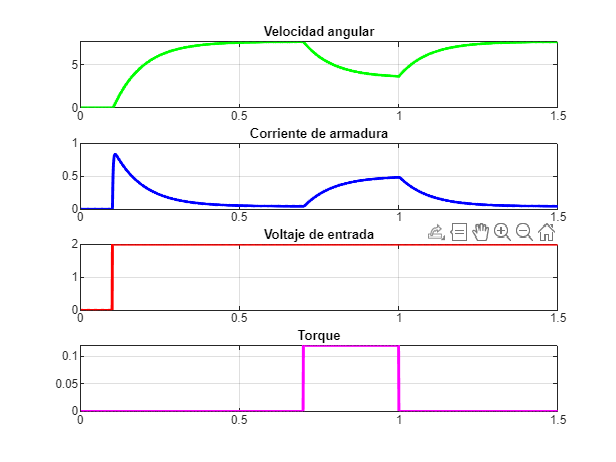

figure(1); % Creación de la figura sin especificar un número, MATLAB asignará automáticamente
hold on

subplot(4,1,1);
plot(t, Wr, 'g', 'LineWidth', 2);
title('Velocidad angular');
grid on;

subplot(4,1,2);
plot(t, Ia, 'b', 'LineWidth', 2);
title('Corriente de armadura');
grid on;

subplot(4,1,3);
plot(t, Va, 'r', 'LineWidth', 2);
title('Voltaje de entrada'); 
grid on;

subplot(4,1,4);
plot(t,Tq, 'm', 'LineWidth', 2);
title('Torque'); 
grid on;
hold off

Aplico Chen

% Apply The Second-Order Systems with differents poles method 

% y(t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(t1/T1))- (((T3-T2)/(T1-T2))*exp(-t1/T2)));
% y(2*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(2*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(2*t1)/T2)));
% y(3*t1)= K*(1+ ((T3-T1)/(T1-T2))*exp(-(3*t1/T1))- (((T3-T2)/(T1-T2))*exp(-(3*t1)/T2)));

% Obtain maximium value from t (RLC circuit measure).
max_t= max(t);

% Define step amplitude.
stepAmplitude= 1;

% Take time and voltage arrays
% Time array.
t0= t;
%Vc array.
y=Wr;

% Chen Method application
% Take three point to apply Chen Method.
% First point time.

%i=155;
i=154;
t_inic= t0(i);
% Define step.
%h= 62;
h=61;
% Obtain y1.
t_t1= t0(i);
y_t1= y(i)

y_t1 = 3.2604

% Obtain y2.
t_2t1= t0(i+h);
y_2t1= y(i+h)

y_2t1 = 5.3744

% Obtain y3.
t_3t1= t0(i+(2*h));
y_3t1= y(i+(2*h))

y_3t1 = 6.4672


% Normalize gain
% Add abs(y(end)), because 'end' take value= -12V (Alternate input signal).
K= abs(y(end))/(stepAmplitude)

K = 7.6185


% Calculating k1, k2, k3.
k1= ((y_t1)/K)-1;
k2= ((y_2t1)/K)-1;
k3= ((y_3t1)/K)-1;

% Calculating b, alfa1, alfa2.
b= 4*(k1^(3))*k3- 3*(k1^2)*(k2^2)- 4*(k2^3)+ (k3^2)+ 6*k1*k2*k3;
alfa1= (k1*k2+ k3- sqrt(b))/(2*((k1^2)+ k2));
alfa2= (k1*k2+ k3+ sqrt(b))/(2*((k1^2)+ k2));

% Calculating Beta.
% beta= (2*(k1^3)+ 3*k1*k2+ k3- sqrt(b))/(sqrt(b));
% Alternative
beta= (k1+alfa2)/(alfa1-alfa2);

% Calculating the estimates of the time constants T1, T2 and T3.
% T1_e= -(t_t1)/(log(alfa1))
% T2_e= -(t_t1)/(log(alfa2)) %imaginary from alfa2
% deltaTime= 5.5e-4
%T1_e= -(5.5e-4)/(log(alfa1));
%T2_e= -(5.5e-4)/(log(alfa2));
%T3_e= beta*(T1_e- T2_e)+ T1_e;

% Add estimates of the time constants T1, T2, T3.
%ii= 1;
%T1(ii)= T1_e;
%T2(ii)= T2_e;
%T3(ii)= T3_e;

% Enhancing estimation accuracy.
%T1_e= sum(T1/ length(T1))
%T2_e= sum(T2/ length(T2))
%T3_e= sum(T3/ length(T3))

% Calculo las ctes de tiempo T1, T2 y T3.
% A t_t1 le resto 0.1 seg. del retardo
T1= -(t_t1-0.1)/(log(alfa1))

T1 = 0.0139

T2= -(t_t1-0.1)/(log(alfa2))

T2 = 0.0824

T3= beta *(T1- T2)+ T1

T3 = 0.0057




% Build Transfer Function
s= tf('s');
sys= K/((T1*s+1)*(T2*s+1)); %%sin retardo
sys1= K*exp(-s*0.1)/((T1*s+1)*(T2*s+1))


sys1 =
 
                           7.619
  exp(-0.1*s) * ----------------------------
                0.001144 s^2 + 0.09627 s + 1
 
Continuous-time transfer function.
Model Properties


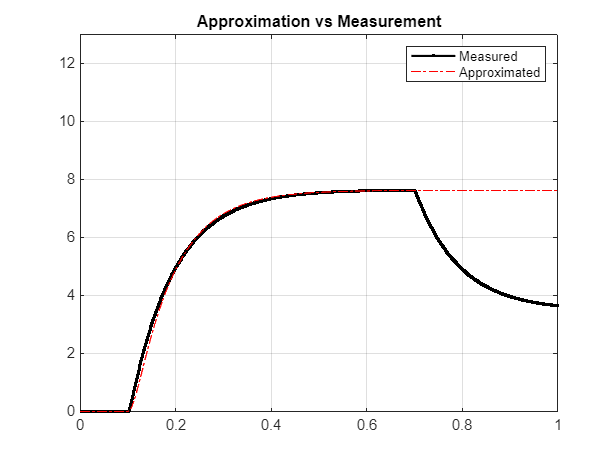

% [num, den]= tfdata(sys, 'v');

% Plot approximated step response
% Obtain step response with delay.
% [ys, ts]= step(sys*exp(-s*0.01), 'r-', 0.16);
figure;
[ys, ts]= step(sys1, 'r-', 1.5);   %aproximada
plot(t, Wr, 'k.-','LineWidth',1.5); %medida 
hold on;
plot(ts, ys, 'r-.');%aproximada
xlim([0, 1]);
ylim([0, 13]);
legend('Measured', 'Approximated');
title('Approximation vs Measurement');
grid on;